# Tutorial 1: Loading a Robot in CASPR

This tutorial introduces the basics in order to load a robot into the CASPR environment using a script.

clear;

## Loading a model configuration

First, instantiate the ModelConfig object with the name of the robot. In this example, the "Example spatial" robot will be used.

model_config = ModelConfig('Example spatial');

The list of available robots can be found within the `CASPR_GUI` or `model_config.robotNamesList`

## Loading a robot model

The `ModelConfig` object is not the robot (kinematics and dynamics) model itself, but must be created. At this point, the "cable set" that define the properties and arrangement of the cables must be specified based on the cable set's ID within the XML cable configuration file.

cdpr_model = model_config.getModel('basic_7_cables');

## Visualise the robot

After a robot model is created, it can be easily visualised using the function `MotionSimulatorBase.PlotFrame(...)`

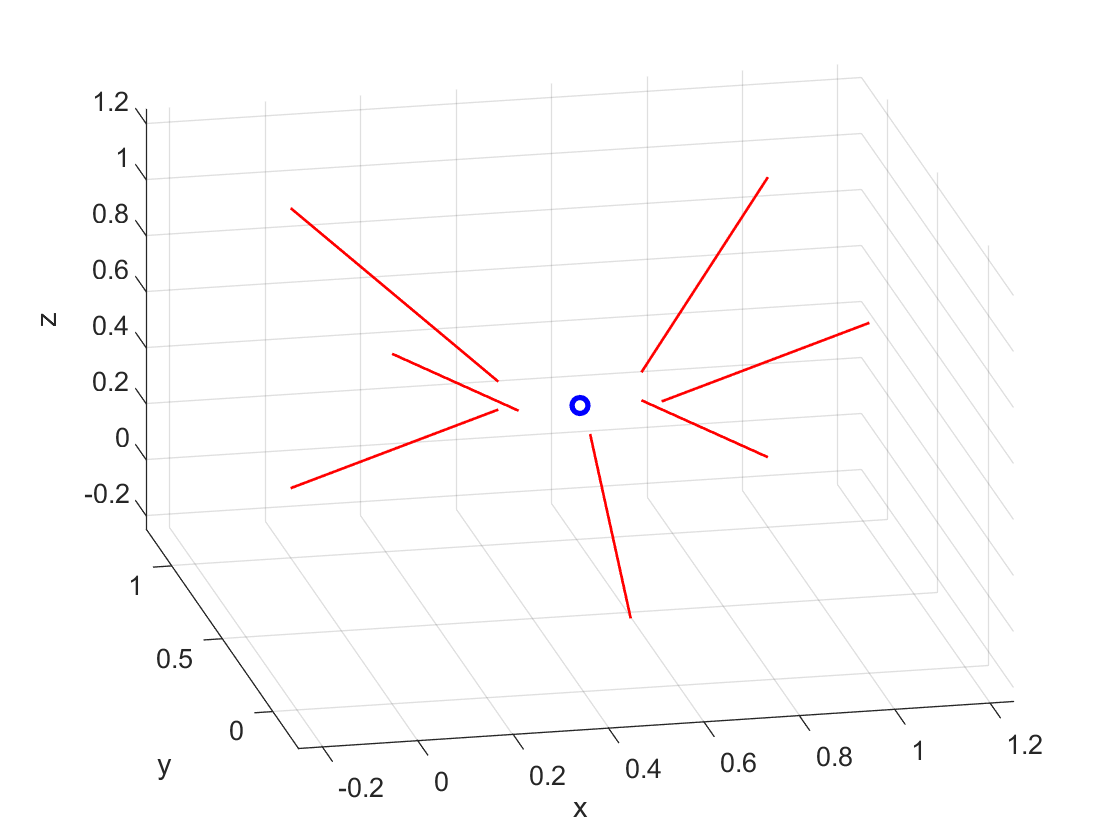

MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle);

## Update the robot pose

The model of the cable robot can be easily updated by providing the joint space position, velocity, acceleration and external wrench

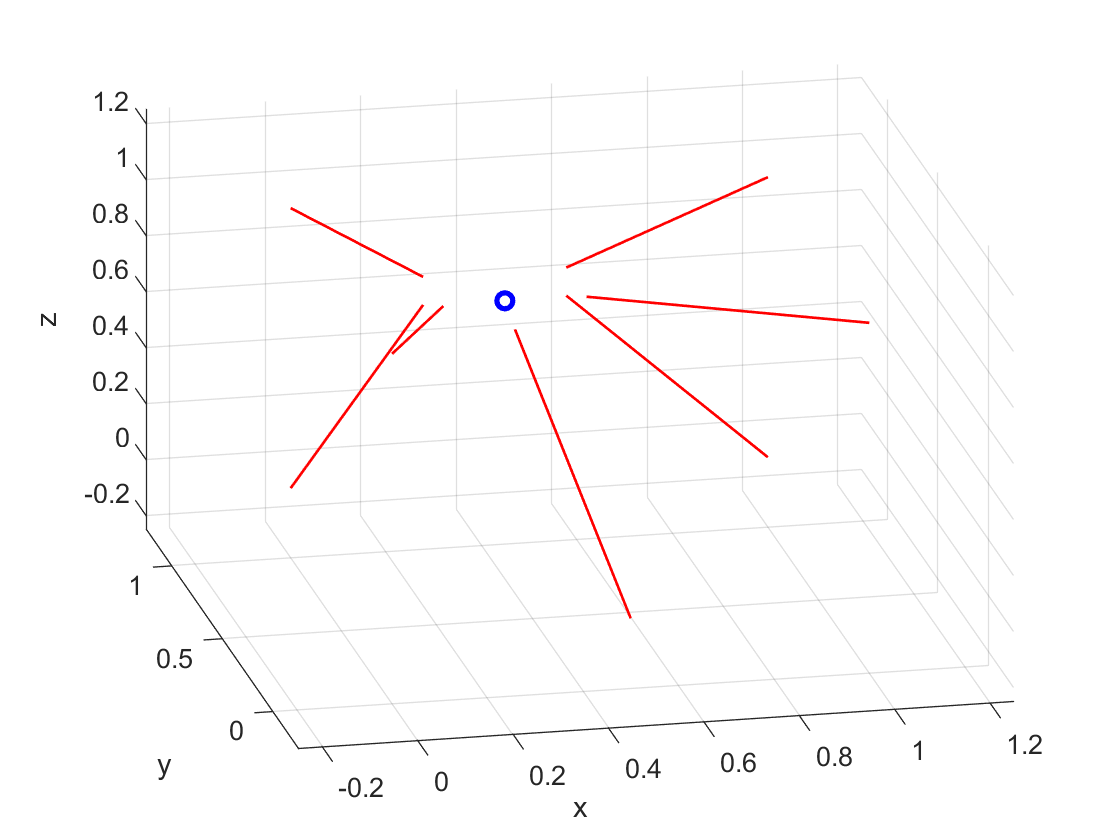

q = [0.3; 0.3; 1.0; 0; 0; 0];
q_dot = [0; 0; 0; 0; 0; 0];
q_ddot = [0; 0; 0; 0; 0; 0];
w_ext = [0; 0; 0; 0; 0; 0];
cdpr_model.update(q, q_dot, q_ddot, w_ext); % Update robot model
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot again

## Loading a different cable configuration

This can be easily achieved by loading a different cable set

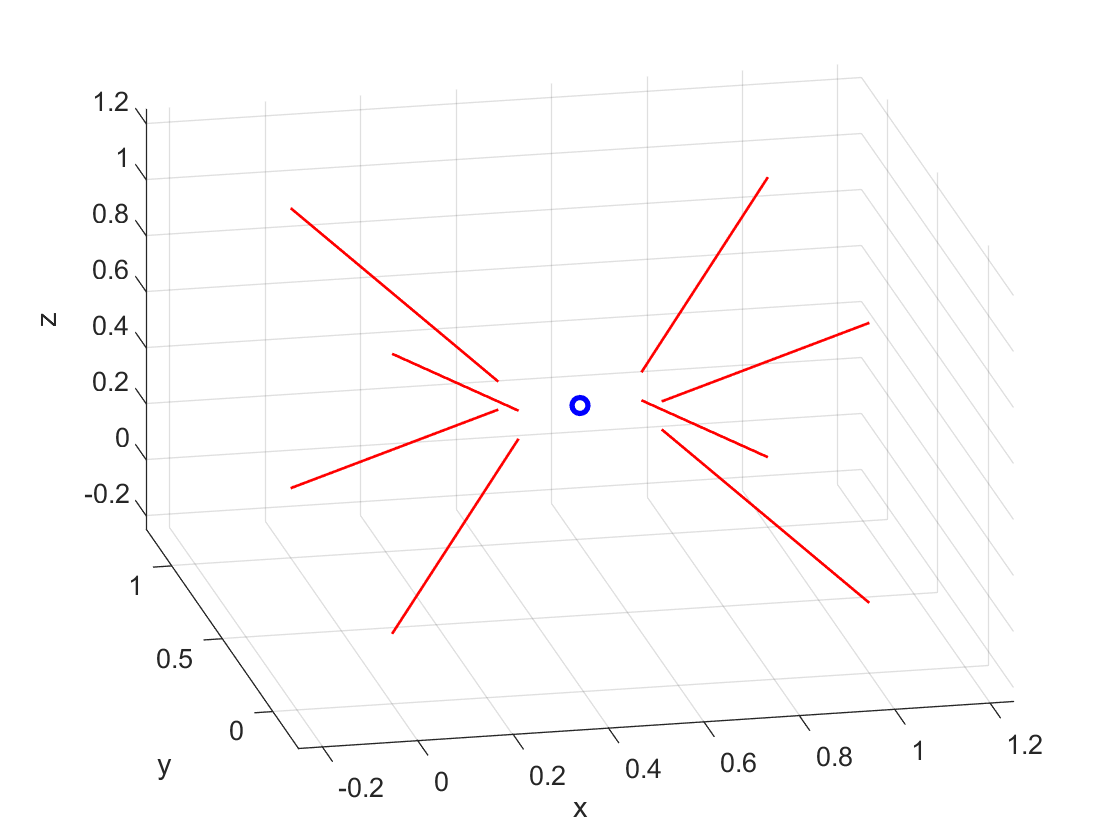

cdpr_model = model_config.getModel('basic_8_cables');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot again